parkingTrainGTfinished = load('parkingTrainGTfinished.mat');
[imds, blds] = objectDetectorTrainingData(parkingTrainGTfinished.gTruth);
countEachLabel(blds)

ans = 3×3 table
      Label       Count    ImageCount
    __________    _____    __________

    Accessible     167        144    
    Charger        106        106    
    EV             223        201    


bboxes = createBoundingBoxTable(blds)

bboxes = 496×3 table
    ImgIdx               BBox                  Label   
    ______    ___________________________    __________

       1      178      89     121     135    EV        
       2      205     108      69     142    Accessible
       3      189      94     101     181    Accessible
       4      209     115      58     134    Accessible
       5      171      98     133     143    EV        
       6        1      75     177     191    EV        
       7       90      57     201     202    EV        
       8      113      44     274     274    EV        
       9      143    68.5     203     252    EV        
      10      203     108      70     141    Accessible
      11      130    60.5     229     260    EV        
      12      158    56.5     165     264    EV        
      13      205     106      73     115    EV        
      13       13     137      45   

bboxes.Area = bboxes.BBox(:,3) .* bboxes.BBox(:,4);
bboxes.AspectRatio = bboxes.BBox(:,3) ./ bboxes.BBox(:,4);
bboxes

bboxes = 496×5 table
    ImgIdx               BBox                  Label       Area     AspectRatio
    ______    ___________________________    __________    _____    ___________

       1      178      89     121     135    EV            16335       0.8963  
       2      205     108      69     142    Accessible     9798      0.48592  
       3      189      94     101     181    Accessible    18281      0.55801  
       4      209     115      58     134    Accessible     7772      0.43284  
       5      171      98     133     143    EV            19019      0.93007  
       6        1      75     177     191    EV            33807       0.9267  
       7       90      57     201     202    EV            40602      0.99505  
       8      113      44     274     274    EV            75076            1  
       9

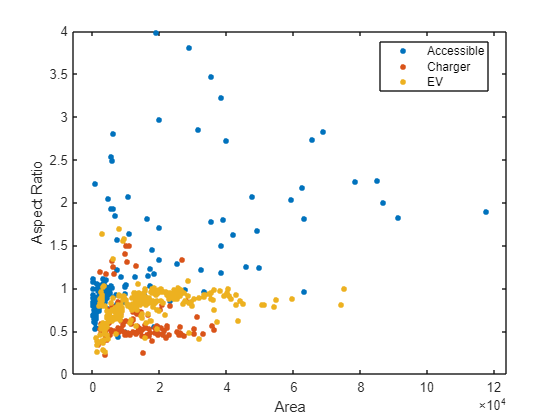

gscatter(bboxes.Area, bboxes.AspectRatio, bboxes.Label)
xlabel("Area")
ylabel("Aspect Ratio")

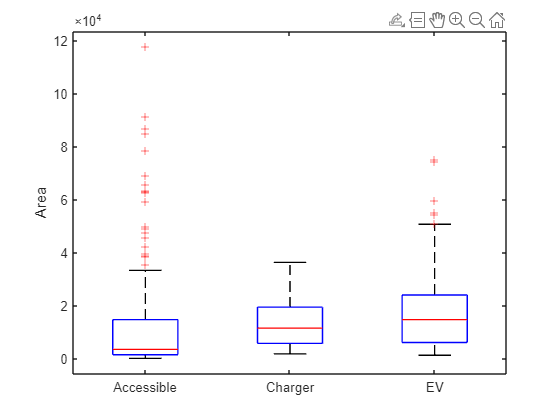

boxplot(bboxes.Area, bboxes.Label)
ylabel("Area")

classes = categories(blds.LabelData{1,2})

classes = 3×1 cell array
    {'Accessible'}
    {'Charger'   }
    {'EV'        }


rng("default");
shuffledIndices = randperm(length(imds.Files));
idx = floor(0.8 * length(shuffledIndices));
trainingIdx = 1:idx;
validationIdx = idx+1 : length(shuffledIndices);

imdsTrain = imageDatastore(imds.Files(trainingIdx));
bldsTrain = boxLabelDatastore(cell2table(blds.LabelData(trainingIdx,:)));
imdsValidation = imageDatastore(imds.Files(validationIdx));
bldsValidation = boxLabelDatastore(cell2table(blds.LabelData(validationIdx,:)));

img = imread(imdsTrain.Files{1});
size(img)

ans =    320   480     3


trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
targetDataSize = [320 480 3]; 
trainingData = transform(trainingData, @(dataIn) resizeDetectionData(dataIn,targetDataSize)); 
validationData = transform(validationData, @(dataIn) resizeDetectionData(dataIn,targetDataSize)); 

detector = yoloxObjectDetector("tiny-coco",classes,"InputSize",targetDataSize);

gpuDevice(1)

ans =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce 840M'
                     Index: 1
         ComputeCapability: '5.0'
            SupportsDouble: 1
     GraphicsDriverVersion: '472.19'
               DriverModel: 'WDDM'
            ToolkitVersion: 11.8000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 2147483648 (2.15 GB)
           AvailableMemory: 1643288987 (1.64 GB)
               CachePolicy: 'balanced'
       MultiprocessorCount: 3
              ClockRateKHz: 1124000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


options=trainingOptions("sgdm", ...
    InitialLearnRate=0.001, ...
    ValidationData=validationData, ...
    MaxEpochs=10, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    MiniBatchSize=8,validationFrequency=32, ...
    ExecutionEnvironment='cpu');

[detector,info] = trainYOLOXObjectDetector(trainingData,detector,options);

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingYoloXLoss    ValidationYoloXLoss
    _____    _________    ___________    _________    _________________    ___________________
      2         50         00:09:31        0.001           1.7304                             
      3         100        00:14:34        0.001           1.7565                             
      4         150        00:19:32        0.001           1.9886                             
      5         200        00:25:08        0.001           1.7907                             
      7         250        00:30:16        0.001           1.3856                             
      8         300        00:36:37        0.001           1.8234                             
      9         350        00:42:0

save('parkingdetector.mat', "detector");

detector = load("parkingYoloXDetectorSolution.mat");

parkingTest = load('parkingTestGT.mat');
[imds, blds] = objectDetectorTrainingData(parkingTest.parkingTestGT);
testData = combine(imds,blds);
testData = transform(testData, @(dataIn) resizeDetectionData(dataIn,targetDataSize)); 

%testResults = detect(detector.detector, testData, "Threshold",0.05);
testResults = detect(detector, testData, "Threshold",0.05, "ExecutionEnvironment","cpu");
%classes = detector.detector.ClassNames;
classes = detector.ClassNames;
[ap, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.5);
mean(ap)

ans = 0.8700

% Vector of detection threshold values to test
thresholds = 0.05:0.05:0.9;

% Create a matrix to store the results
% Each column is the AP returned for the corresponding threshold value
apMatrix = zeros(length(classes), length(thresholds));

% Create a waitbar to monitor progress
f = waitbar(0);

% Loop through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector.detector, testData, "Threshold", thresholds(ii));
    apMatrix(:,ii) = evaluateDetectionPrecision(results, testData, 0.5);
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% Calculate the mAP for each threshold
% The mean function calculates the mean of each column of the matrix
mAPList = mean(apMatrix);

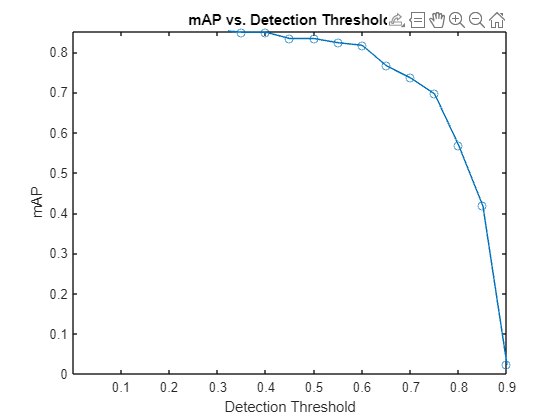

plot(thresholds, mAPList, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")

vertcat(info.ValidationYoloXLoss)

ans = 400×1 single column vector
    9.6667
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


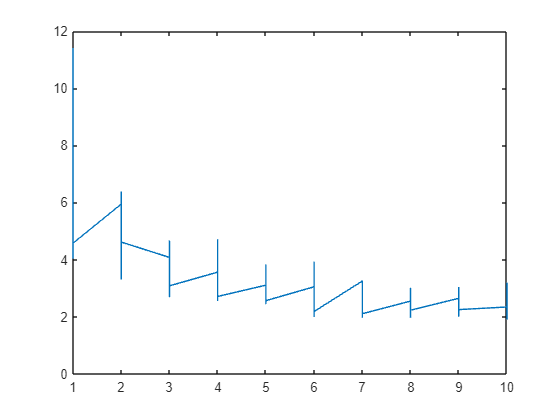

plot(vertcat(info.Epoch), vertcat(info.TrainingYoloXLoss), vertcat(info.Epoch), vertcat(info.ValidationYoloXLoss))

vertcat(info.TrainingYoloXLoss)

ans = 400×1 single column vector
    9.8883
   11.4020
    7.9789
    6.7252
   10.6512
    7.5104
    6.4777
    6.8721
    7.8669
    7.4425


function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extract the label data
    data = blds.LabelData;

    % Initialize variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Loop through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Loop through the objects in the image 
        % Add the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Create the output table
    bboxes = table(ImgIdx, BBox, Label);
end